# **Численные методы в СПб АУ РАН**

## **Задание по практике №4**

Кузьмичев Артём, 4 курс

## **№6 (алгоритмы и программы к разделу 2.4)**

*Изначальный вид программы 2.5 *

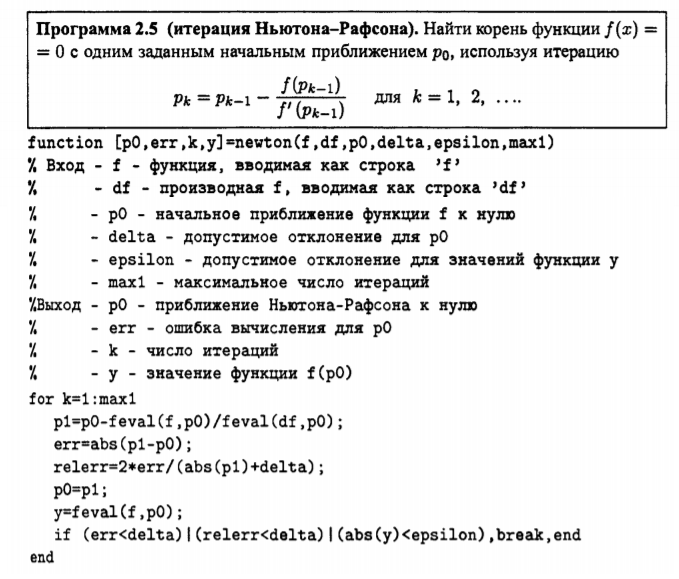

Итерационная формула Хейли:

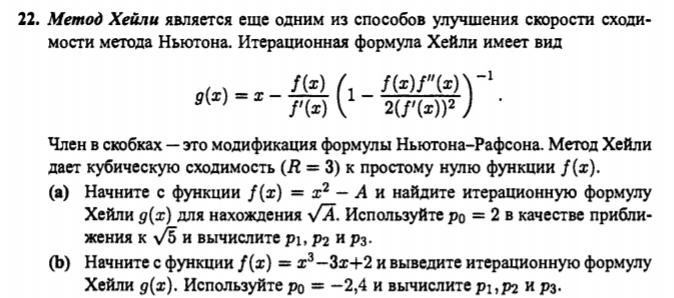

#### Реализуем вход для функции

syms symF(x)
symF(x) =  x.^3 - 3*x + 2 ;    % функция

Посчитаем производную из полученной на вход функции

symDF = diff(symF)

$$symDF(x) = 3\,x^{2}-3$$

Кроме того, для метода Хелли потребуется посчитать вторую производную функции:

symD2F = diff(symF,2)

$$symD2F(x) = 6\,x$$

## Метод Хелли

Изначально, метод Ньютона-Рафсона предлагал такой шаг для получения следующего приближения


$$p_1 =p_0 -\frac{f\left(p_0 \right)}{f^{\prime } \left(p_0 \right)}$$


Его модификация, рассматриваемая в данной задаче, позволит ускорить сходимость алгоритма. Итерационный шаг Хелли выглядит следующим образом


$$p_1 =p_0 -\frac{f\left(p_0 \right)}{f^{\prime } \left(p_0 \right)}{\left(1-\frac{f\left(p_0 \right){f^{\prime } }^{\prime } \left(p_0 \right)}{2{\left(f\prime \left(p_0 \right)\right)}^2 }\right)}^{-1}$$


#### Вход алгоритмов

f   = matlabFunction(symF);
df  = matlabFunction(symDF);
d2f = matlabFunction(symD2F);

precision = 20;             %количество цифр
digits(precision);
p0 = vpa(-240);             % начальное приближение нуля  функции

delta = 1e-8;               % допустимое отклонение для p
epsilon = 1e-8;             % допустимое отклонение для значений функции у
maxit = 30;                 % максимальное число итераций

verbosity = 1;              % Указать 1 для вывода информации об итерации во время выполнения алгоритма. 0 - silent mode
verbT = 5;                  % Период вывода информации, если verbosity == 1

## Алгоритм

Ниже алгоритм будет выполнен дважды - с использованием множителя Хелли и без такового. Управляющая булевая переменная *UseHalleyMethod*

***Метод Ньютона***

UseHalleyMethod = 0;
[poutN, NewtonPk] = NewtonMethod(f, df, p0, delta, epsilon, maxit, verbosity, verbT, UseHalleyMethod, d2f);

Итерация 5 	 Значение посчитанного приближения на данной итерации: -47.423811 
 Значение функции в этой точке: -31548.263780 
 Oшибка вычисления: 1.5794e+01 
 Oтносительная ошибка вычисления: 9.9864e-01 
 Итерация 10 	 Значение посчитанного приближения на данной итерации: -6.381897 
 Значение функции в этой точке: -68.804231 
 Oшибка вычисления: 2.0034e+00 
 Oтносительная ошибка вычисления: 9.1513e-01 
 Итерация 15 	 Значение посчитанного приближения на данной итерации: -2.003379 
 Значение функции в этой точке: -0.000068 
 Oшибка вычисления: 3.3714e-03 
 Oтносительная ошибка вычисления: 3.3714e-03 
 Алгоритм завершил работу на итерации k = 16. Приблизительное значение нуля функции pout = -2.000000 

***Метод Хелли***

UseHalleyMethod = 1;
[poutH, HalleyPk] = NewtonMethod(f, df, p0, delta, epsilon, maxit, verbosity, verbT, UseHalleyMethod, d2f);

Итерация 5 	 Значение посчитанного приближения на данной итерации: -15.057243 
 Значение функции в этой точке: -417.347869 
 Oшибка вычисления: 7.4387e+00 
 Oтносительная ошибка вычисления: 1.9528e+00 
 Итерация 10 	 Значение посчитанного приближения на данной итерации: -2.000001 
 Значение функции в этой точке: -0.000000 
 Oшибка вычисления: 1.0742e-06 
 Oтносительная ошибка вычисления: 1.0742e-06 
 Алгоритм завершил работу на итерации k = 10. Приблизительное значение нуля функции pout = -2.000000 

Истинные значения нулей функции. Нас интересует значение -2, к которому мы и приближаемся от точки $p_0$

sols = solve(f(x)==0)

$$sols = \left(\begin{array}{c} -2\\ 1\\ 1 \end{array}\right)$$

root = sols(1)

$$root = -2$$

Посчитаем растояние от истинного корня на каждой итерации в наших методах

NewtonErrors = abs(NewtonPk - root);
HalleyErrors = abs(HalleyPk - root );

Сравним скорость сходимости данных методов

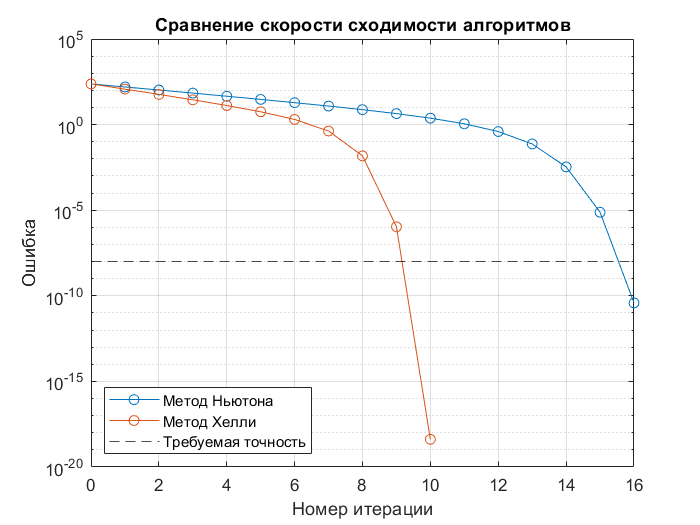

semilogy(0:length(NewtonErrors)-1,NewtonErrors,'-o');
grid on
hold on
semilogy(0:length(HalleyErrors)-1,HalleyErrors,'-o');
yline(epsilon,'k--');
title('Сравнение скорости сходимости алгоритмов');
legend('Метод Ньютона','Метод Хелли','Требуемая точность','Location','southwest');
xlabel('Номер итерации');
ylabel('Ошибка');
hold off

## Количественное сравнение скорости сходимости

Теоретические источники указывают на квадратичную сходимость метода Ньютона ($\beta =2$) и кубическую сходимость ($\beta =3$) у метода Хелли (правда, есть *нюансы*).

Скорость сходимости $\beta$ определяется из уравнения.

## 
$$\left|x_{k+1} -x_{\mathrm{true}} \right|<\alpha {\left|x_k -x_{\mathrm{true}} \right|}^{\beta }$$


На практике это можно сделать, оценив на логарифмическом графики тангенс угла наклона зависимости 

## 
$$\mathrm{log}\left|x_{k+1} -x_{\mathrm{true}} \right|<\mathrm{log}\alpha +\beta \cdot \mathrm{log}\left|x_k -x_{\mathrm{true}} \right|$$


#### Вычисления

Для дальнейших вычислений получим массив ошибок $\left|x_{k-1} -x_{\mathrm{true}} \right|$ - "предыдущие ошибки" и массив $\left|x_{k+1} -x_{\mathrm{true}} \right|$ - "новые ошибки"

Их следует перевести в double для возмножности осуществить фит

NDE1 = double(NewtonErrors(1:end-1));   % предыдущие ошибки метода Ньютона
NDE2 = double(NewtonErrors(2:end));     % новые ошибки метода Ньютона

HDE1 = double(HalleyErrors(1:end-1));   % предыдущие ошибки метода Хелли
HDE2 = double(HalleyErrors(2:end));     % новые ошибки метода Хелли

#### Метод Ньютона

Определим параметры прямой, наилучшим образом приближающей данную зависимость в двойном логарифмическом масштабе

NewtonConvergencyFit = polyfit(log(NDE1),log(NDE2), 1);
fprintf('Параметры фита - Метод Ньютона: \n Скорость сходимости: \n β = %f (Теоретическое значение β ⪅ 2) \n Коэффициент: \n log(α) = %f \n', NewtonConvergencyFit(1), NewtonConvergencyFit(2));

Параметры фита - Метод Ньютона: 
 Скорость сходимости: 
 β = 1.651858 (Теоретическое значение β ⪅ 2) 
 Коэффициент: 
 log(α) = -2.472977 


И построим прямую вместе с зависмостью на одном графике

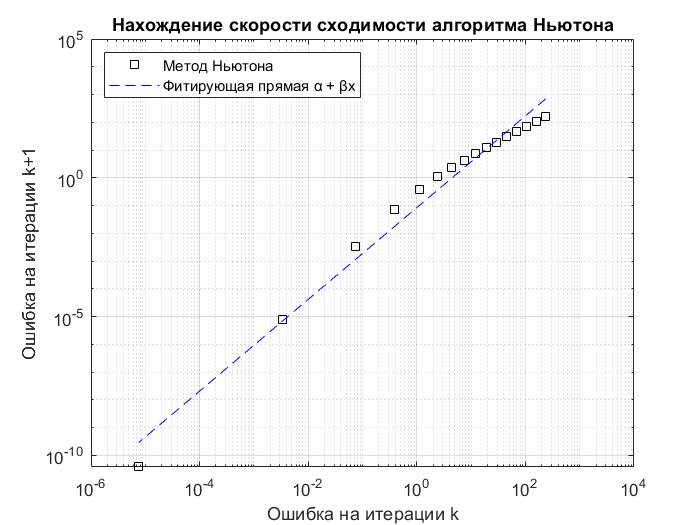

loglog(NDE1, NDE2,'sk');
grid on
hold on

yNewton = exp(polyval(NewtonConvergencyFit,log(NDE1)));
loglog(NewtonErrors(1:end-1), yNewton,'--b');

title('Нахождение скорости сходимости алгоритма Ньютона');
legend('Метод Ньютона','Фитирующая прямая α + βx','Location','northwest');
xlabel('Ошибка на итерации k');
ylabel('Ошибка на итерации k+1');


hold off

#### Метод Хелли

Определим параметры прямой, наилучшим образом приближающей  зависимость в двойном логарифмическом масштабе

HalleyConvergencyFit = polyfit(log(HDE1),log(HDE2), 1);
fprintf('Параметры фита - Метод Хелли: \n Скорость сходимости: \n β = %f (Теоретическое значение β ⪅ 3) \n Коэффициент: \n log(α) = %f \n', HalleyConvergencyFit(1), HalleyConvergencyFit(2))

Параметры фита - Метод Хелли: 
 Скорость сходимости: 
 β = 2.472878 (Теоретическое значение β ⪅ 3) 
 Коэффициент: 
 log(α) = -5.341473 


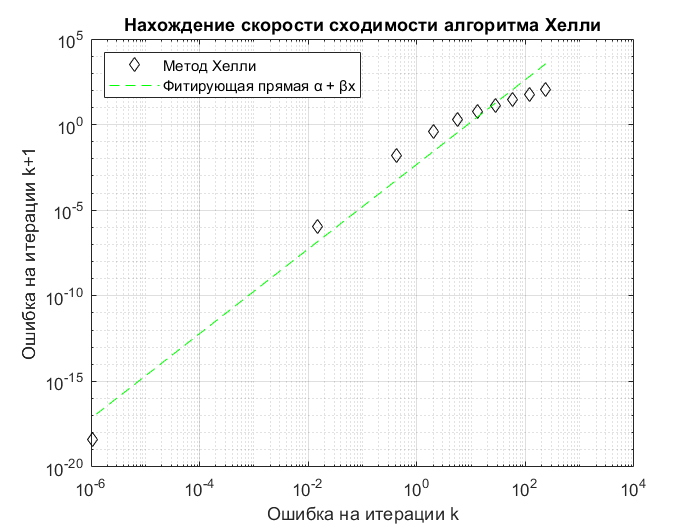


loglog(HDE1, HDE2,'dk');
grid on
hold on
yHalley = exp(polyval(HalleyConvergencyFit, log(HDE1)));
loglog(HalleyErrors(1:end-1), yHalley,'g--');

title('Нахождение скорости сходимости алгоритма Хелли');
legend('Метод Хелли','Фитирующая прямая α + βx','Location','northwest');
xlabel('Ошибка на итерации k');
ylabel('Ошибка на итерации k+1');

#### Выводы

Полученные значения $\beta \approx 1\ldotp 65$ для метода Ньютона и $\beta \approx 2\ldotp 47$ для метода Хелли , что указывает на то, что скорость сходимости у последнего действительно выше

## Приложение

#### Определение функции, осуществляющей алгоритмы Ньютона и Хелли

function [pout, p] = NewtonMethod(f, df, p0, delta, epsilon, maxit, verbosity, verbT,  UseHalleyMethod, d2f)
    arguments
        f function_handle               % функция
        df function_handle              % производная
        p0                              % начальное приближение
        delta double = 1e-8             % минимальное изменение за итерацию
        epsilon double = 1e-8           % точность нахождения нуля функции
        maxit int8 = 20                 % максимальное число итераций
        verbosity int8 = 0              % boolean. Вывод информации об итерациях на экран
        verbT int8  = 5                 % Период вывода информации об итерациях на экран, если verbosity = 1
        UseHalleyMethod int8 = 0        % Использовать метод Хелли
        d2f = 0                         % вторая производная функции для метода Хелли
    end
    
    % Выход:
        % pout                          %найденное значение корня
        % p                             %список со значенями приближений на каждой итерации
    
                                            
p(1)= p0; %начальное приближение

for k=1:maxit
    
    if UseHalleyMethod == 1
        HalleyMultiplier =  (1 - f(p(k))*d2f(p(k))/(2*(df(p(k)))^2))^(-1);
    else 
        HalleyMultiplier =  1;
    end
    
    p(k+1)=p(k)-(f(p(k))/df(p(k)))*HalleyMultiplier ; % p(k+1) - Полученное на k-й итерации приближение
    err=abs(p(k+1)-p(k)); % ошибка вычисления
    relerr=2*err/(abs(p(k+1))+delta);
    
    y=f(p(k+1));
    
    if verbosity == 1 % вывод информации об итерации
        if mod(k,verbT) == 0
            fprintf("Итерация %d \t ", k);
            fprintf("Значение посчитанного приближения на данной итерации: %f \n ", p(k));
            fprintf("Значение функции в этой точке: %f \n ", y);
            fprintf("Oшибка вычисления: %.4e \n ", err);
            fprintf("Oтносительная ошибка вычисления: %.4e \n ", relerr);
        end
    end
    
    % проверка условий выхода из цикла
    pout = p(k+1);
    
    if (err<delta)||(relerr<delta)||(abs(y)<epsilon) % в связи с малостью изменений
        fprintf("Алгоритм завершил работу на итерации k = %d. Приблизительное значение нуля функции pout = %f ", k, pout);
        break;
    end
    
    if (k == maxit) % достигнуто максимальное число итераций
        fprintf("Достигнуто максимальное число итераций k = %d. Приблизительное значение нуля функции pout = %f ", k, pout);
        break;
    end
    
end
end